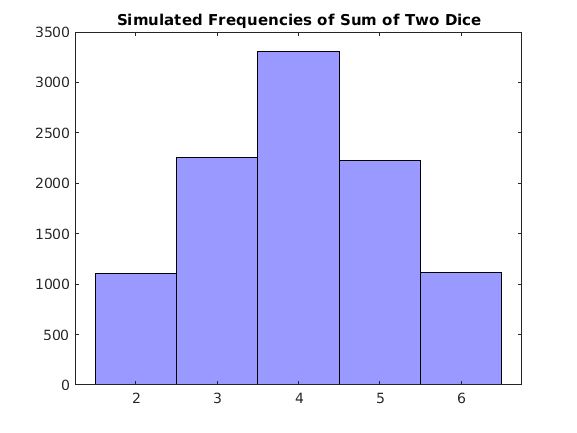

% D1 = random variable of the number rolled on the first die, values can be {1,2,3}
% D2 = random variable of the number rolled on the second die, values can be {1,2,3}
% X = random variable of the sum of the numbers of D1 and D2, so X = D1 +
% D2. Values of X can be x = {2,3,4,5,6}

format longG; 

% set the seed so data is reproducible
rng(123);

% number of times to simulate the values 
N = 10000;

% generate a 1 x N matrix of the values 1,2,3, which have probabilities
% 1/3 each. Do this for both dice.
% NOTE: this is equivalent to generating 1,1,2,2,3,3 each with
% probability 1/6. 
%D1 = randsrc(1, N, [1,1,2,2,3,3; 1/6, 1/6, 1/6, 1/6, 1/6, 1/6]);
%D2 = randsrc(1, N, [1,1,2,2,3,3; 1/6, 1/6, 1/6, 1/6, 1/6, 1/6]);
%D1 = randsrc(1, N, [1,2,3; 1/3, 1/3, 1/3]);
%D2 = randsrc(1, N, [1,2,3; 1/3, 1/3, 1/3]);

% NOTE: max value is 3 because we sample from 1,2,3:
D1 = randi(3, 1, N); 
D2 = randi(3, 1, N); 

% Now random variable X is just the sum: 
X = D1 + D2; 

% Tabulating the values to get the frequency of each roll
xs = unique(X);
freqs = zeros(size(xs));
for i = 1:length(xs)
    freqs(i) = length(find(X == xs(i)));
end

% Drawing the histogram of frequencies
drawFrequencies(X);


% Simulated and actual probabilities:
xValues = 2:6;
simProbs = freqs / N; 
actualProbs = [4, 8, 12, 8, 4]/36;

% Creating custom comparison table, transposing each argument here to
% make them column vectors in this table. 
result = table(xValues', simProbs', actualProbs', 'VariableNames', {'X', 'SimulatedProbs', 'ActualProbs'});
result

result = 5×3 table
    X    SimulatedProbs       ActualProbs   
    _    ______________    _________________

    2    0.1106            0.111111111111111
    3    0.2256            0.222222222222222
    4    0.3303            0.333333333333333
    5    0.2222            0.222222222222222
    6    0.1113            0.111111111111111


function drawFrequencies(simulatedXValues)
    histogram(simulatedXValues, 'FaceColor', 'b', 'FaceAlpha', 0.4);
    hold on; 
    title('Simulated Frequencies of Sum of Two Dice');
end

